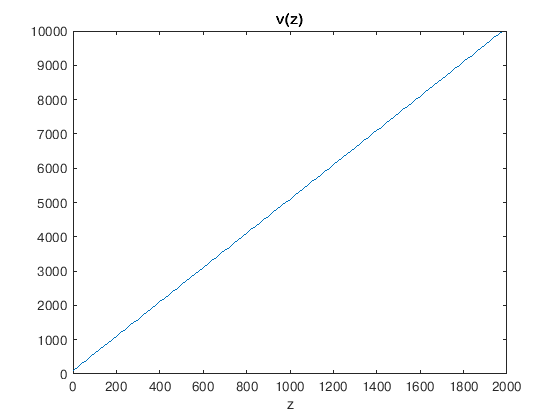

%sampling in depth
dz=20.; %m
nz=100;
z=(0:nz-1)*dz; Z=max(z);

%v(z)=k*z+b
k=5.; %m/s/m
b=100.; %m/s
v=k*z+b;
%v=b*log(z+dz);
%v=b/2.*sin(k*z)+b;
%v=b+b*atan(z/100.);
%v=b+b*atan(b./z);
plot(z,v); xlabel('z'); title('v(z)')

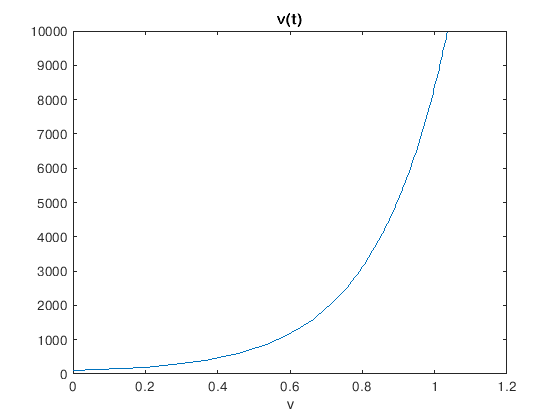


%velocity in time domain
dt=zeros(1,nz);
dt(2:nz)=dz./v(1:nz-1);
t=cumsum(dt);

plot(t,v); xlabel('v'); title('v(t)')


$$C\left\lbrack v\left(z\right)\right\rbrack :=\int_0^{+\infty } v\left(z\right)e^{-\sigma z} \mathrm{dz}$$



$$C\left\lbrack v\left(t\right)\right\rbrack =\int_0^{+\infty } {v\left(t\right)}^2 e^{-\sigma \int_0^t v\left(\tau \;\right)d\tau \;} \;\mathrm{dt}$$



$$K_{v\left(z\right)} =e^{-\sigma z}$$



$$K_{v\left(t\right)} \left(z\right)=2v\left(z\right)e^{-\sigma z} +\int_z^{+\infty } v\left(z^{\prime } \right){\;d\;e}^{-\sigma z^{\prime } } =v\left(z\right)e^{-\sigma z} -\int_z^{+\infty } {\;e}^{-\sigma z^{\prime } } \mathrm{dv}\left(z^{\prime } \right)$$


**Verify**:


$$K_{v\left(t\right)} \left(z\right)=2K_{v\left(z\right)} v\left(z\right)+\int_z^{+\infty \;} v\left(z_p \right)dK_{v\left(z_p \right)}$$


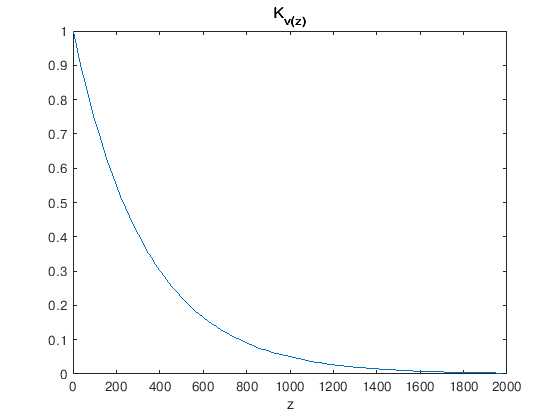

%K_v(z)
sig=3e-3; %good
%sig=3e-4; %poor 
Kvz=exp(-sig*z);
plot(z,Kvz); xlabel('z'); title('K_{v(z)}')

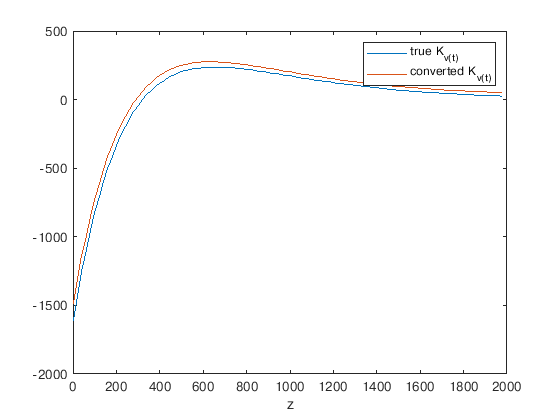


%K_v(t)
tmp=v; tmp(1:nz-1)=diff(v); tmp(nz)=tmp(nz-1);
%compute integration by matrix-vector product
L=eye(nz)+tril(ones(nz),-1); %lower triangular matrix
true = v.*exp(-sig*z) -(tmp.*exp(-sig*z))*L;
plot(z,true); xlabel('z');
hold on

%converted K_v(t)
tmp=Kvz; tmp(1:nz-1)=diff(Kvz); tmp(nz)=tmp(nz-1);
Kvt = 2*Kvz.*v + (v.*tmp)*L;

plot(z,Kvt); xlabel('z');

legend('true K_{v(t)}','converted K_{v(t)}')
hold off

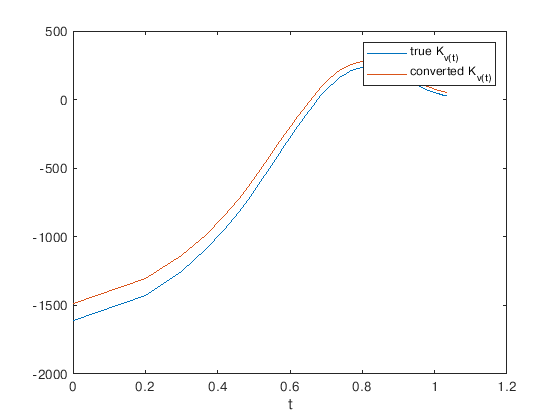


%plot in time domain
plot(t,true,t,Kvt); xlabel('t')
legend('true K_{v(t)}','converted K_{v(t)}')

%regular sample v(t) in time
rdt=0.02;
rt=0:0.02:0.6; %1.0355;
nrt=size(rt,2);

rvt=interp1(t,v,rt);
plot(rt,rvt); title('regularly sampled v(t)')

%approximate partial derivatives
C0=fobj(v,sig,z,dz);
dCdvt=zeros(1,nrt);
for i=1  %1:nrt
    eta=zeros(1,nrt); eta(i)=1;
    alpha=rvt(i)*0.1;
    dCdvt(i) = (fobj(interp1(rt,rvt+alpha*eta,t,'linear','extrap'),sig,z,dz)-C0)/alpha;
end

plot(rt,dCdvt); title('approx')

function C=fobj(v,s,z,dz)
    C = sum( v .* exp(-s*z) ) *dz;
end